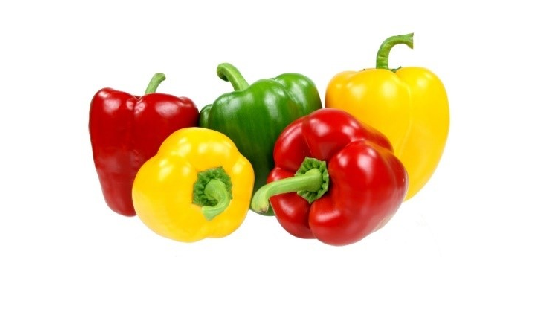

%Read in image and ask for the color of the object to highlight
origIm = imread('peppers.jpg');
Im = origIm;
imshow(Im)

color = input('Enter color (roygbiv): ','s')

color = 'g'

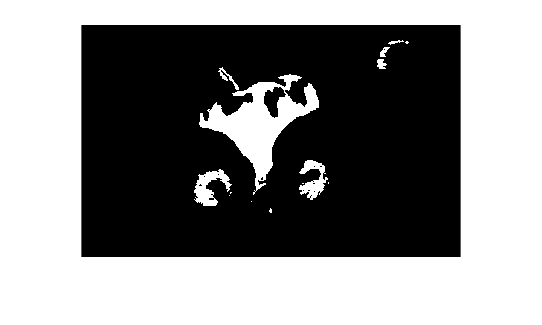


%Convert to binary image keeping the desired color as white(1) and others black(0)
if color == 'r'
    subject = ( (Im(:,:,1)>Im(:,:,2)+Im(:,:,3)) & (Im(:,:,1)>Im(:,:,2)*2) & (Im(:,:,1)>Im(:,:,3)*2) );
end
if color == 'o'
subject = ( (Im(:,:,1)>Im(:,:,2)) & (Im(:,:,2)>Im(:,:,3)) );
end
if color == 'y'
    subject = ( (((Im(:,:,1)-Im(:,:,2)>-25)) & ((Im(:,:,1)-Im(:,:,2)<25))) & (Im(:,:,3)<100) );
end
if color == 'g'
    subject =  ( (Im(:,:,2)>(Im(:,:,1)+Im(:,:,3))) );
end
if color == 'b'
    subject =  (Im(:,:,3)>(Im(:,:,1)+Im(:,:,2)) & (Im(:,:,3)>220) );
end
if color == 'i'
    subject =  (Im(:,:,3)>(Im(:,:,1)+Im(:,:,2)) & (Im(:,:,3)>200) );
end
if color == 'v'
    subject =  (Im(:,:,3)>(Im(:,:,1)+Im(:,:,2)) & (Im(:,:,3)>150) );
end

imshow(subject)

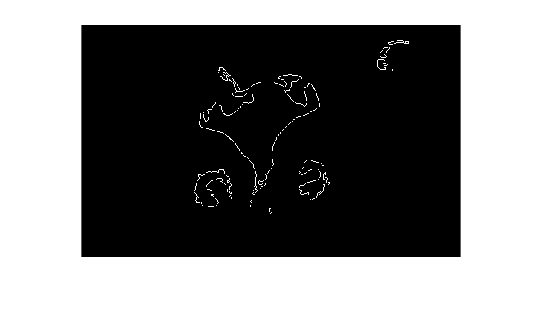

Im = imfill(subject,'holes');           %Fill in any holes in the white part of image
Im = edge(Im);                          %Take only the edges of the white parts, using sobels method
Outline = bwareafilt(Im,1);             %Take only the largest portion
imshow(Im)

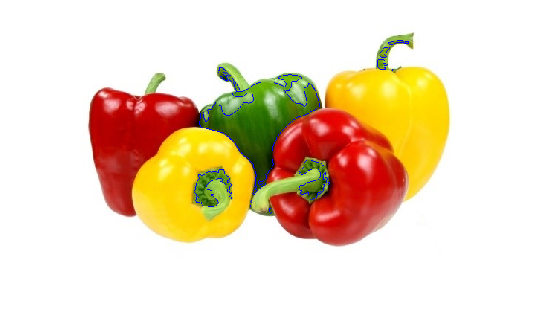

imshow(Outline)

B = imoverlay(origIm,Im,'blue');   %Overlay the outline as blue over the original image
imshow(B)